## Blatt 4

### Aufgabe 1

h=0.1;x0=0.6;

### 1.1 Zweipunkte-Formel

df2p=@(h,x0)(fx(x0)-fx(x0-h))./h;
df2p(h,x0)

ans =    0.033005451469264


### 1.2 Dreipunkte-Endpunkt-Formel

df3pe=@(h,x0)1./(2*h).*(-3*fx(x0)+4*fx(x0+h)-fx(x0+2*h));
df3pe(h,x0)

ans =    0.038797928949271


### 1.3 Dreipunkte-Mittelpunkt-Formel

df3pm =@(h,x0)(fx(x0 + h) - fx(x0 - h))./(2*h);
df3pm(h,x0)

ans =    0.038609406011272


### 1.4 Fünfpunkte-Mittelpunkt-Formel

df5pm = @(h,x0)(fx(x0 - 2.*h) - 8.*fx(x0 - h) + 8.*fx(x0 + h) -fx(x0 + 2.*h))./(12*h);
df5pm(h,x0)

ans =    0.038614573572267


## Aufgabe 2

### 2.1 x_0 =0.6

h = logspace(-5,0,1000);
g1=h;
g2=h.^2;
g3=h.^4;
G=[g1;g2;g3];
x0=0.6*ones(size(h)); % 需要和h保持一样维度
% dy精确解
dy_exact=dfx(x0(1)); 
% dy不同算法的解析解
dy_2p=arrayfun(df2p,h,x0);
dy_3pe=arrayfun(df3pe,h,x0);
dy_3pm=arrayfun(df3pm,h,x0);
dy_5pm=arrayfun(df5pm,h,x0);
% 组合解析解
dynummeric=[dy_2p;dy_3pe;dy_3pm;dy_5pm]

dynummeric = 1.0e+09 *

   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.000000000038623   0.00000000003

% 计算误差
Error=arrayfun(@(x) abs(dy_exact-x),dynummeric)

Error = 1.0e+09 *

   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001   0.000000000000001 

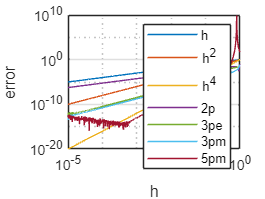

% 画图
loglog(h,G,h,Error)
%loglog(h,Error(1,:),'r-',h,Error(2,:),'g-',h,Error(3,:),'b-',h,Error(1,:),'k-',h,g1,'k-.',h,g2,'k:',h,g3,'k--');

legend('h','h^2','h^4','2p','3pe','3pm','5pm')
grid on
xlabel('h'),ylabel('error')

legend()

function y=fx(x)
y=(x/(1+x))^5;
end

function y=dfx(x)
y=5*(x/(x+1))^4.*(1./(1+x)^2);
% 化简 ：y=5.*x^4./(x+1)^6
end